## Sergiu Iliev | Bayesian ML Course | Final | Problem 2 - continued

clc, clear

## Load dataset to continue from Python

T = readtable('DF.csv');           % Create a temporary table to import the data

Define a forecast range and dataset select dataset subsections for traning and testing (forecasting) solar power levels

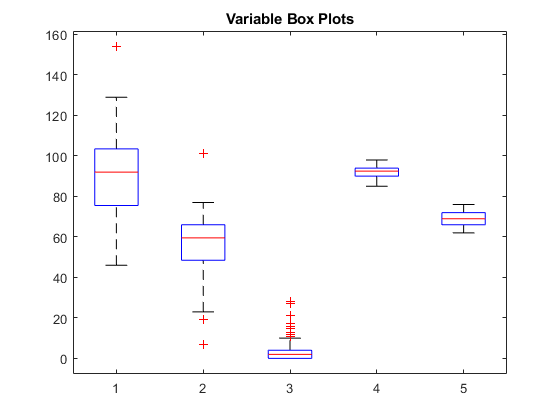

fh = 10; % 10 day forecast horizon
y = T.Energy(1:(end - fh));         % Define Train Energy vector 
yF = T.Energy((end - fh + 1):end);  % Define Forecast Energy vector

T = removevars(T,{'Date','Energy'}); % Keep only the predictor variables in the table
X = table2array(T);                  
X = X(1:(end - fh),:);                % Create the predictor array for training
XF = X((end - fh + 1):end,:);         % Create the predictor array for testing
predictornames = T.Properties.VariableNames(); % Create a vector of the predictor names

figure;
boxplot(X);

title('Variable Box Plots');
T = readtable('DF.csv');           % Regenerate the temporary table
% DF = transpose(load('DF.mat'));  % load dataset
% X = transpose(load('X.mat'));    % load training dataset
% y = transpose(load('y.mat'));    % load testing dataset
% fnames = fieldnames(Y);
% T = table;
% for i = 1:length(fnames)
%     x_T = table(num2cell(getfield(Y, fnames{i})));
%     x_T.Properties.VariableNames = {fnames{i}};
%     T = [T, x_T];
% end

## (d)-continued: Constructing a Bayesian Linear Regression Model with a LASSO prior

rng('default')                      % For reproducibility

lambda = 1;                         % Specify a regularization value of 1

B = lasso(X,y,'Lambda',lambda, 'PredictorNames',predictornames) % Construct the posterior linear regression model using the data.

B =     0.4437
  -19.5910
   36.3150
  392.2673
 -261.1158


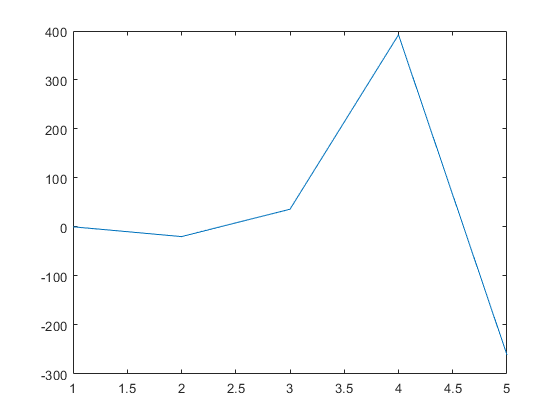

% [LassoBetaEstimates,FitInfo] = lasso(X,y,'PredictorNames',predictornames);

plot(B)                             % Plot the posterior probability distribution

## (d) Better implementation of the part above

p = size(X,2); % Number of predictors

PriorMdl = bayeslm(p,'ModelType','lasso','VarNames',predictornames);
table(PriorMdl.Lambda,'RowNames',PriorMdl.VarNames)

ans = 6×1 table
                 Var1
                 ____

    Intercept    0.01
    PM25            1
    PM10            1
    NO2             1
    maxT            1
    minT            1


`PriorMdl` is a `lassoblm` model object. `lassoblm` attributes a shrinkage of `1` for each coefficient except the intercept, which has a shrinkage of `0.01`

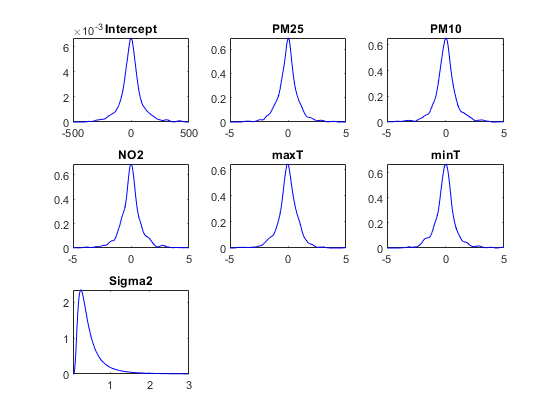

plot(PriorMdl)

The plot above is the Prior Distribution, now we will determine the Posterior

## (e) Constructing and Plotting the Posterior

[EstMdl,Summary] = estimate(PriorMdl,X,y,'Display',true)


Method: lasso MCMC sampling with 10000 draws
Number of observations: 76
Number of predictors:   6
 
           |      Mean            Std                  CI95            Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -2579.5929      4596.5734      [-11695.474, 6339.483]       0.287     Empirical  
 PM25      |    -0.0011         0.1605          [-0.341,  0.340]         0.491     Empirical  
 PM10      |   -27.7022        10.2465         [-47.636, -7.502]         0.004     Empirical  
 NO2       |    35.5817        27.4746         [-18.926, 89.730]         0.908     Empirical  
 maxT      |   323.1037        54.2471         [217.678, 430.160]        1.000     Empirical  
 minT      |  -222.3267        51.7202        [-324.413, -120.520]       0.000     Empirical  
 Sigma2    |     1.3505e+06     2.1813e+05  [989107.013, 1841377.775]    1.000     Empirical  
 


EstMdl =   empiricalblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
        BetaDraws: [6×10000 double]
      Sigma2Draws: [1×10000 double]

 
           |      Mean            Std                  CI95            Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -2579.5929      4596.5734      [-11695.474, 6339.483]       0.287     Empirical  
 PM25      |    -0.0011         0.1605          [-0.341,  0.340]         0.491     Empirical  
 PM10      |   -27.7022        10.2465         [-47.636, -7.502]         0.004     Empirical  
 NO2       |    35.5817        27.4746         [-18.926, 89.730]         0.908     Empirical  
 maxT      |   323.1037        54.2471         [217.678, 430.160]        1.000     Empirical  
 minT      |  -222.3267        51.7202        [-324.413, -120.520]       0.00

Summary = 7×6 table
                    Mean          Std                  CI95              Positive    Distribution     Covariances 
                 __________    __________    ________________________    ________    _____________    ____________

    Intercept       -2579.6        4596.6        -11695        6339.5     0.2875     {'Empirical'}    [1×7 double]
    PM25         -0.0011389       0.16053      -0.34113       0.34004     0.4909     {'Empirical'}    [1×7 double]
    PM10            -27.702        10.247       -47.636       -7.5023      0.004     {'Empirical'}    [1×7 double]
    NO2              35.582        27.475       -18.926         89.73     0.9085     {'Empirical'}    [1×7 double]
    maxT 

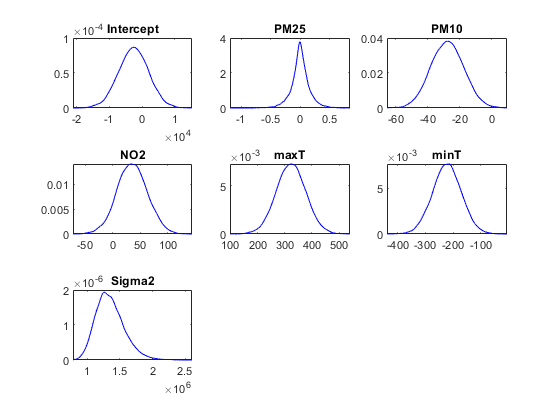

plot(EstMdl)

The plot above is the Posterior distribution for Lambda = 1

**Evaluating the model FMSE** 

% Fit a lasso regression model to the data. Use the default regularization path. lasso standardizes the data by default.
[LassoBetaEstimates,FitInfo] = lasso(X,y,'Standardize',false,...
    'PredictorNames',predictornames);
% Compute the FMSE of each model returned by lasso.
yFLasso = FitInfo.Intercept + XF*LassoBetaEstimates;
fmseLasso = sqrt(mean((yF - yFLasso).^2,1)); fmseLasso(2)

ans = 2.7914e+03

yFBayesLasso = forecast(EstMdl,XF);
fmseBayesLasso = sqrt(mean((yF - yFBayesLasso).^2));
mean(fmseBayesLasso)

ans = 2.7867e+03

## f) PM25 Prior Alteration and effects on Posterior and RMSE

**Changing the Lambda for PM25 from 1 to 100 and recalculating posterior**

PriorMdl.Lambda(2) = 100

PriorMdl =   lassoblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
           Lambda: [6×1 double]
                A: 3
                B: 1

 
           |  Mean     Std           CI95         Positive   Distribution  
---------------------------------------------------------------------------
 Intercept |  0       100    [-200.000, 200.000]    0.500   Scale mixture  
 PM25      |  0      0.0100    [-0.020,  0.020]     0.500   Scale mixture  
 PM10      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 NO2       |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 maxT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 minT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 Sigma2    | 0.5000  0.5000    [ 0.138,  1.616]     1.000   IG(3.00,    1) 
 

[EstMdl,Summary] = estimate(PriorMdl,X,y,'Display',true)


Method: lasso MCMC sampling with 10000 draws
Number of observations: 76
Number of predictors:   6
 
           |      Mean            Std                  CI95            Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -1793.1094      4751.3242      [-11063.464, 7565.865]       0.344     Empirical  
 PM25      |    -3.6371         6.6841         [-17.798,  8.953]         0.297     Empirical  
 PM10      |   -25.0113        11.3359         [-47.363, -2.808]         0.014     Empirical  
 NO2       |    33.9925        27.2863         [-19.555, 86.685]         0.895     Empirical  
 maxT      |   315.4981        54.9623         [209.924, 423.502]        1.000     Empirical  
 minT      |  -220.8353        51.9689        [-323.503, -119.161]       0.000     Empirical  
 Sigma2    |     1.3400e+06     2.1341e+05  [986048.351, 1819575.345]    1.000     Empirical  
 


EstMdl =   empiricalblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
        BetaDraws: [6×10000 double]
      Sigma2Draws: [1×10000 double]

 
           |      Mean            Std                  CI95            Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -1793.1094      4751.3242      [-11063.464, 7565.865]       0.344     Empirical  
 PM25      |    -3.6371         6.6841         [-17.798,  8.953]         0.297     Empirical  
 PM10      |   -25.0113        11.3359         [-47.363, -2.808]         0.014     Empirical  
 NO2       |    33.9925        27.2863         [-19.555, 86.685]         0.895     Empirical  
 maxT      |   315.4981        54.9623         [209.924, 423.502]        1.000     Empirical  
 minT      |  -220.8353        51.9689        [-323.503, -119.161]       0.00

Summary = 7×6 table
                   Mean         Std                  CI95              Positive    Distribution     Covariances 
                 ________    __________    ________________________    ________    _____________    ____________

    Intercept     -1793.1        4751.3        -11063        7565.9     0.3439     {'Empirical'}    [1×7 double]
    PM25          -3.6371        6.6841       -17.798        8.9531     0.2966     {'Empirical'}    [1×7 double]
    PM10          -25.011        11.336       -47.363       -2.8084     0.0139     {'Empirical'}    [1×7 double]
    NO2            33.993        27.286       -19.555        86.685     0.8955     {'Empirical'}    [1×7 double]
    maxT     

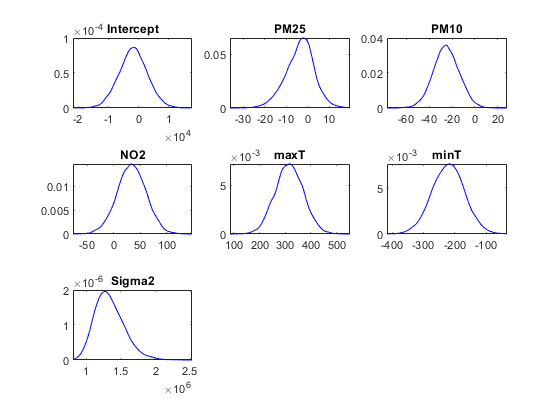

plot(EstMdl)

The plot above is the Posterior distribution for PM25 Lambda = 100

**Evaluating the model FMSE** 

yFBayesLasso = forecast(EstMdl,XF);
fmseBayesLasso = sqrt(mean((yF - yFBayesLasso).^2));
mean(fmseBayesLasso)

ans = 2.7896e+03

**Changing the Lambda for PM25 from 1 to 10000 and recalculating posterior**

PriorMdl.Lambda(2) = 100

PriorMdl =   lassoblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
           Lambda: [6×1 double]
                A: 3
                B: 1

 
           |  Mean     Std           CI95         Positive   Distribution  
---------------------------------------------------------------------------
 Intercept |  0       100    [-200.000, 200.000]    0.500   Scale mixture  
 PM25      |  0      0.0100    [-0.020,  0.020]     0.500   Scale mixture  
 PM10      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 NO2       |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 maxT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 minT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 Sigma2    | 0.5000  0.5000    [ 0.138,  1.616]     1.000   IG(3.00,    1) 
 

[EstMdl,Summary] = estimate(PriorMdl,X,y,'Display',true)


Method: lasso MCMC sampling with 10000 draws
Number of observations: 76
Number of predictors:   6
 
           |      Mean            Std                  CI95            Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -1795.7640      4772.0365      [-11321.199, 7611.227]       0.357     Empirical  
 PM25      |    -3.6639         6.7034         [-17.508,  9.243]         0.294     Empirical  
 PM10      |   -24.8351        11.3127         [-47.103, -2.439]         0.015     Empirical  
 NO2       |    33.6236        27.6746         [-20.369, 87.994]         0.890     Empirical  
 maxT      |   315.8333        55.6313         [206.498, 425.390]        1.000     Empirical  
 minT      |  -221.3632        51.8956        [-322.985, -120.247]       0.000     Empirical  
 Sigma2    |     1.3427e+06     2.1519e+05  [989487.917, 1834540.023]    1.000     Empirical  
 


EstMdl =   empiricalblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
        BetaDraws: [6×10000 double]
      Sigma2Draws: [1×10000 double]

 
           |      Mean            Std                  CI95            Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -1795.7640      4772.0365      [-11321.199, 7611.227]       0.357     Empirical  
 PM25      |    -3.6639         6.7034         [-17.508,  9.243]         0.294     Empirical  
 PM10      |   -24.8351        11.3127         [-47.103, -2.439]         0.015     Empirical  
 NO2       |    33.6236        27.6746         [-20.369, 87.994]         0.890     Empirical  
 maxT      |   315.8333        55.6313         [206.498, 425.390]        1.000     Empirical  
 minT      |  -221.3632        51.8956        [-322.985, -120.247]       0.00

Summary = 7×6 table
                    Mean          Std                  CI95              Positive    Distribution     Covariances 
                 __________    __________    ________________________    ________    _____________    ____________

    Intercept       -1795.8          4772        -11321        7611.2     0.3567     {'Empirical'}    [1×7 double]
    PM25            -3.6639        6.7034       -17.508        9.2431     0.2945     {'Empirical'}    [1×7 double]
    PM10            -24.835        11.313       -47.103       -2.4391     0.0146     {'Empirical'}    [1×7 double]
    NO2              33.624        27.675       -20.369        87.994     0.8896     {'Empirical'}    [1×7 double]
    maxT 

SLRMdlFull = fitlm(X,y,'VarNames',T.Properties.VariableNames(2:end))

SLRMdlFull = Linear regression model:
    minT ~ 1 + Energy + PM25 + PM10 + NO2 + maxT

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)    -1556.8     5290.7    -0.29425       0.76944
    Energy         -5.9438     8.9961    -0.66071       0.51097
    PM25           -23.458     12.639      -1.856      0.067664
    PM10            33.406     29.454      1.1342       0.26059
    NO2             315.44      60.54      5.2104    1.8132e-06
    maxT           -222.42     55.435     -4.0123     0.0001487


Number of observations: 76, Error degrees of freedom: 70
Root Mean Squared Error: 1.23e+03
R-squared: 0.39,  Adjusted R-Squared: 0.347


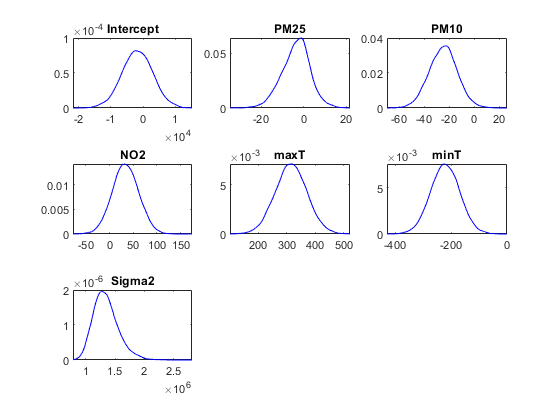

plot(EstMdl)

The plot above is the Posterior distribution for PM25 Lambda = 10000

**Evaluating the model FMSE** 

yFBayesLasso = forecast(EstMdl,XF);
fmseBayesLasso = sqrt(mean((yF - yFBayesLasso).^2));
mean(fmseBayesLasso)

ans = 2.7880e+03

## Forecasting

Fit a Linear Model for Comparison

SLRMdlFull = fitlm(X,y,'VarNames',T.Properties.VariableNames(2:end))

SLRMdlFull = Linear regression model:
    minT ~ 1 + Energy + PM25 + PM10 + NO2 + maxT

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)    -1556.8     5290.7    -0.29425       0.76944
    Energy         -5.9438     8.9961    -0.66071       0.51097
    PM25           -23.458     12.639      -1.856      0.067664
    PM10            33.406     29.454      1.1342       0.26059
    NO2             315.44      60.54      5.2104    1.8132e-06
    maxT           -222.42     55.435     -4.0123     0.0001487


Number of observations: 76, Error degrees of freedom: 70
Root Mean Squared Error: 1.23e+03
R-squared: 0.39,  Adjusted R-Squared: 0.347


## Results Interpretation:

Increasing the value of the Lasso shrinkage parameter Lambda, reduces the influence of the predictor variable. In the case of PM25:

- when Lambda = 1, FRMSE = 2787 

- when Lambda = 100, FRMSE = 2790

- when Lambda = 10000, FRMSE = 2788

These results suggest that PM25 has a minor contribution to the prediction capacity of the model. As we approach turning off this parameter by increasing Lambda to 10000 the RMSE does not change.

Therefore PM25 is an unimportant predictor variable.

## g) PM10 Prior Alterationa and effects on Posterior and RMSE

**Changing the Lambda for PM25 from 1 to 100 and recalculating posterior**

PriorMdl.Lambda(3) = 100

PriorMdl =   lassoblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
           Lambda: [6×1 double]
                A: 3
                B: 1

 
           |  Mean     Std           CI95         Positive   Distribution  
---------------------------------------------------------------------------
 Intercept |  0       100    [-200.000, 200.000]    0.500   Scale mixture  
 PM25      |  0      0.0100    [-0.020,  0.020]     0.500   Scale mixture  
 PM10      |  0      0.0100    [-0.020,  0.020]     0.500   Scale mixture  
 NO2       |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 maxT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 minT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 Sigma2    | 0.5000  0.5000    [ 0.138,  1.616]     1.000   IG(3.00,    1) 
 

[EstMdl,Summary] = estimate(PriorMdl,X,y,'Display',true)


Method: lasso MCMC sampling with 10000 draws
Number of observations: 76
Number of predictors:   6
 
           |      Mean            Std                  CI95             Positive  Distribution 
-----------------------------------------------------------------------------------------------
 Intercept | -1819.1573      4880.1771       [-11314.392, 7638.331]       0.352     Empirical  
 PM25      |    -5.9489         6.8705          [-20.311,  6.502]         0.188     Empirical  
 PM10      |   -15.4871        10.3390          [-36.715,  2.806]         0.058     Empirical  
 NO2       |    24.7916        27.4699          [-28.991, 78.964]         0.817     Empirical  
 maxT      |   314.2101        56.1702          [205.218, 424.424]        1.000     Empirical  
 minT      |  -223.0117        52.4490         [-328.343, -120.366]       0.000     Empirical  
 Sigma2    |     1.3752e+06     2.1991e+05  [1007242.185, 1872316.897]    1.000     Empirical  
 


EstMdl =   empiricalblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
        BetaDraws: [6×10000 double]
      Sigma2Draws: [1×10000 double]

 
           |      Mean            Std                  CI95             Positive  Distribution 
-----------------------------------------------------------------------------------------------
 Intercept | -1819.1573      4880.1771       [-11314.392, 7638.331]       0.352     Empirical  
 PM25      |    -5.9489         6.8705          [-20.311,  6.502]         0.188     Empirical  
 PM10      |   -15.4871        10.3390          [-36.715,  2.806]         0.058     Empirical  
 NO2       |    24.7916        27.4699          [-28.991, 78.964]         0.817     Empirical  
 maxT      |   314.2101        56.1702          [205.218, 424.424]        1.000     Empirical  
 minT      |  -223.0117        52.4490         [-328.343, -120.366]   

Summary = 7×6 table
                    Mean          Std                  CI95              Positive    Distribution     Covariances 
                 __________    __________    ________________________    ________    _____________    ____________

    Intercept       -1819.2        4880.2        -11314        7638.3      0.352     {'Empirical'}    [1×7 double]
    PM25            -5.9489        6.8705       -20.311        6.5022     0.1878     {'Empirical'}    [1×7 double]
    PM10            -15.487        10.339       -36.715        2.8062     0.0581     {'Empirical'}    [1×7 double]
    NO2              24.792         27.47       -28.991        78.964     0.8169     {'Empirical'}    [1×7 double]
    maxT 

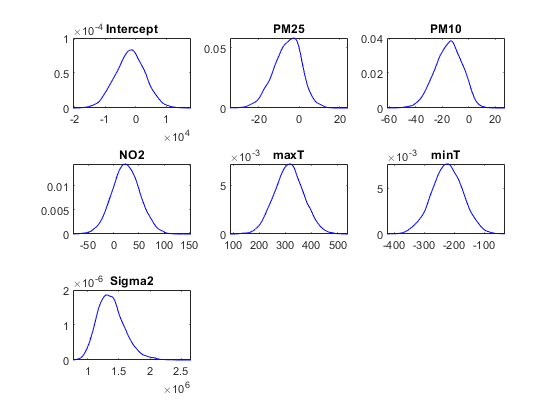

plot(EstMdl)

The plot above is the Posterior distribution for PM10 Lambda = 100

**Evaluating the model FMSE** 

yFBayesLasso = forecast(EstMdl,XF);
fmseBayesLasso = sqrt(mean((yF - yFBayesLasso).^2));
mean(fmseBayesLasso)

ans = 2.7612e+03

**Changing the Lambda for PM25 from 1 to 10000 and recalculating posterior**

PriorMdl.Lambda(3) = 10000

PriorMdl =   lassoblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
           Lambda: [6×1 double]
                A: 3
                B: 1

 
           |  Mean     Std           CI95         Positive   Distribution  
---------------------------------------------------------------------------
 Intercept |  0       100    [-200.000, 200.000]    0.500   Scale mixture  
 PM25      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 PM10      |  0      0.0001    [-0.000,  0.000]     0.500   Scale mixture  
 NO2       |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 maxT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 minT      |  0       1        [-2.000,  2.000]     0.500   Scale mixture  
 Sigma2    | 0.5000  0.5000    [ 0.138,  1.616]     1.000   IG(3.00,    1) 
 

[EstMdl,Summary] = estimate(PriorMdl,X,y,'Display',true)


Method: lasso MCMC sampling with 10000 draws
Number of observations: 76
Number of predictors:   6
 
           |      Mean           Std                  CI95             Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -672.0733      4966.0646       [-10391.819, 9118.265]       0.447     Empirical  
 PM25      |  -14.1946         7.4351          [-28.728,  0.546]         0.030     Empirical  
 PM10      |   -0.0056         0.1682           [-0.364,  0.337]         0.487     Empirical  
 NO2       |   12.4457        25.8196          [-37.996, 63.150]         0.687     Empirical  
 maxT      |  300.2241        57.3047          [186.429, 412.692]        1.000     Empirical  
 minT      | -221.9849        52.9240         [-325.395, -119.192]       0.000     Empirical  
 Sigma2    |    1.4036e+06     2.2660e+05  [1034611.768, 1920640.068]    1.000     Empirical  
 


EstMdl =   empiricalblm with properties:

    NumPredictors: 5
        Intercept: 1
         VarNames: {6×1 cell}
        BetaDraws: [6×10000 double]
      Sigma2Draws: [1×10000 double]

 
           |      Mean           Std                  CI95             Positive  Distribution 
----------------------------------------------------------------------------------------------
 Intercept | -672.0733      4966.0646       [-10391.819, 9118.265]       0.447     Empirical  
 PM25      |  -14.1946         7.4351          [-28.728,  0.546]         0.030     Empirical  
 PM10      |   -0.0056         0.1682           [-0.364,  0.337]         0.487     Empirical  
 NO2       |   12.4457        25.8196          [-37.996, 63.150]         0.687     Empirical  
 maxT      |  300.2241        57.3047          [186.429, 412.692]        1.000     Empirical  
 minT      | -221.9849        52.9240         [-325.395, -119.192]       0.00

Summary = 7×6 table
                    Mean          Std                 CI95              Positive    Distribution     Covariances 
                 __________    _________    ________________________    ________    _____________    ____________

    Intercept       -672.07       4966.1        -10392        9118.3     0.4469     {'Empirical'}    [1×7 double]
    PM25            -14.195       7.4351       -28.728       0.54614     0.0298     {'Empirical'}    [1×7 double]
    PM10         -0.0056079      0.16823       -0.3636       0.33675     0.4872     {'Empirical'}    [1×7 double]
    NO2              12.446        25.82       -37.996         63.15     0.6868     {'Empirical'}    [1×7 double]
    maxT     </

SLRMdlFull = fitlm(X,y,'VarNames',T.Properties.VariableNames(2:end))

SLRMdlFull = Linear regression model:
    minT ~ 1 + Energy + PM25 + PM10 + NO2 + maxT

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)    -1556.8     5290.7    -0.29425       0.76944
    Energy         -5.9438     8.9961    -0.66071       0.51097
    PM25           -23.458     12.639      -1.856      0.067664
    PM10            33.406     29.454      1.1342       0.26059
    NO2             315.44      60.54      5.2104    1.8132e-06
    maxT           -222.42     55.435     -4.0123     0.0001487


Number of observations: 76, Error degrees of freedom: 70
Root Mean Squared Error: 1.23e+03
R-squared: 0.39,  Adjusted R-Squared: 0.347


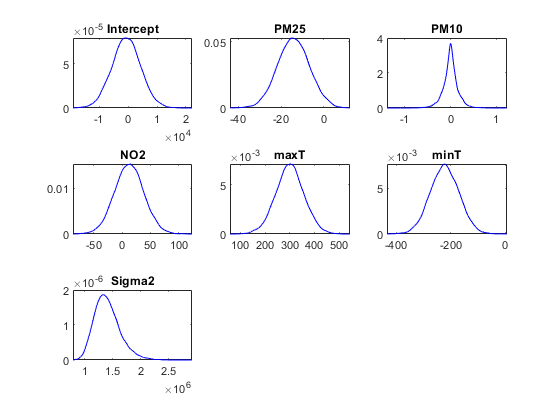

plot(EstMdl)

The plot above is the Posterior distribution for PM10 Lambda = 10000

**Evaluating the model FMSE** 

yFBayesLasso = forecast(EstMdl,XF);
fmseBayesLasso = sqrt(mean((yF - yFBayesLasso).^2));
mean(fmseBayesLasso)

ans = 2.7361e+03

**Forecasting & Results Interpretation:**

Increasing the value of the Lasso shrinkage parameter Lambda, reduces the influence of the predictor variable. In the case of PM10:

- when Lambda = 1, FRMSE = 2787 

- when Lambda = 100, FRMSE = 27612

- when Lambda = 10000, FRMSE = 2723

These results suggest that PM10 has a minor contribution to the prediction capacity of the model. As we approach turning off this parameter by increasing Lambda to 10000 the RMSE does not change.

Similarly these results sugges PM10 is an unimportant predictor variable.

## e) Model Forecasting Plot

Selecting the PM10 model with lambda = 1 and PM25 model with lambda = 100

PriorMdl.Lambda(3) = 1;
PriorMdl.Lambda(1) = 100;
[EstMdl,Summary] = estimate(PriorMdl,X,y,'Display',true);


Method: lasso MCMC sampling with 10000 draws
Number of observations: 76
Number of predictors:   6
 
           |      Mean          Std                 CI95            Positive  Distribution 
-------------------------------------------------------------------------------------------
 Intercept |    0.0871      16.3853         [-33.088, 34.285]         0.502     Empirical  
 PM25      |   -7.0128       7.8197         [-22.375,  8.084]         0.182     Empirical  
 PM10      |  -22.9849      11.8176         [-46.186,  0.135]         0.026     Empirical  
 NO2       |   29.8274      24.9835         [-17.871, 79.596]         0.885     Empirical  
 maxT      |  299.7063      37.4389         [226.176, 374.317]        1.000     Empirical  
 minT      | -222.7302      50.6031        [-321.986, -123.126]       0.000     Empirical  
 Sigma2    |    1.3438e+06   2.1964e+05  [982034.146, 1843525.581]    1.000     Empirical  
 


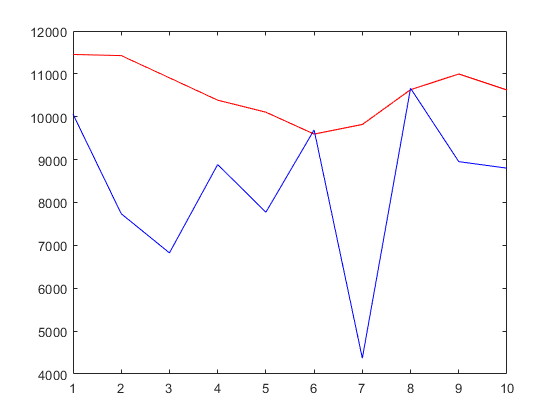

yFBayesLasso = forecast(EstMdl,XF);
plot(yFBayesLasso,'color','red'); 
hold on
plot(yF,'color','blue')

## extra) Hyperparameter Sweep and Best Model Selection

The previous approach only considered the fluctuation of PM10 and PM25, the Lasso method can allow us to adjust the shrinkage valua automatically to turn of predictor variables that do not have an impact on the model's predictive power. This section considers a Hyprparameter sweep and selects the best model

% Fit a lasso regression model to the data. 
[LassoBetaEstimates,FitInfo] = lasso(X,y,'PredictorNames',predictornames);

% Compute the FMSE of each model returned by lasso.
yFLasso = FitInfo.Intercept + XF*LassoBetaEstimates;
fmseLasso = sqrt(mean((yF - yFLasso).^2,1)); fmseLasso(1)

ans = 2.7914e+03

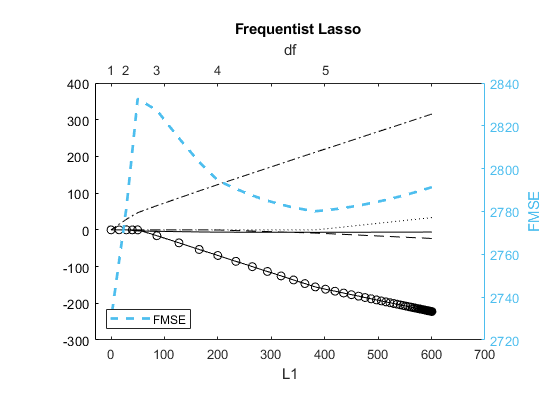

% Plot the magnitude of the regression coefficients with respect to the shrinkage value.
hax = lassoPlot(LassoBetaEstimates,FitInfo);
L1Vals = hax.Children.XData;
yyaxis right
h = plot(L1Vals,fmseLasso,'LineWidth',2,'LineStyle','--');
legend(h,'FMSE','Location','SW');
ylabel('FMSE');
title('Frequentist Lasso')

%% Determine the Best Lasso Model -- the plot above suggests the best results (FMSE around 2720) are obtained when including just one predictor variable
fmsebestlasso = min(fmseLasso(FitInfo.DF == 1));
idx = fmseLasso == fmsebestlasso;
bestLasso = [FitInfo.Intercept(idx); LassoBetaEstimates(:,idx)];
table(bestLasso,'RowNames',["Intercept" predictornames])

ans = 6×1 table
                 bestLasso
                 _________

    Intercept       10491 
    PM25                0 
    PM10                0 
    NO2                 0 
    maxT          3.7e-14 
    minT                0 


**The frequentist lasso analysis suggests that the variables maxT predictor has the strongest predictive power.**

To see how the other variables combare let us compute the shrinkage parameter for each of the 5:

fmsebestlasso = min(fmseLasso(FitInfo.DF == 5));
idx = fmseLasso == fmsebestlasso;
bestLasso = [FitInfo.Intercept(idx); LassoBetaEstimates(:,idx)];
table(bestLasso,'RowNames',["Intercept" predictornames])

ans = 6×1 table
                 bestLasso
                 _________

    Intercept        2451 
    PM25          -6.6516 
    PM10          -10.016 
    NO2            2.6471 
    maxT           220.46 
    minT          -161.68 


This suggest minT has the strongest predictive power after maxT (negatively correlated). Then PM25 and PM10 are either insignificant or redundant, compared to them PM10 has a stronger predictive power. 